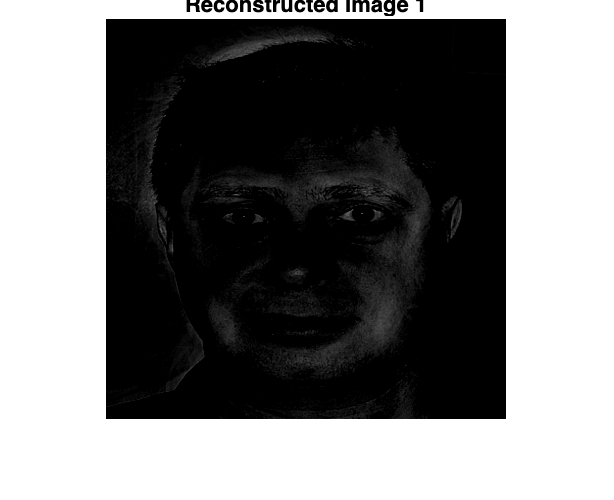

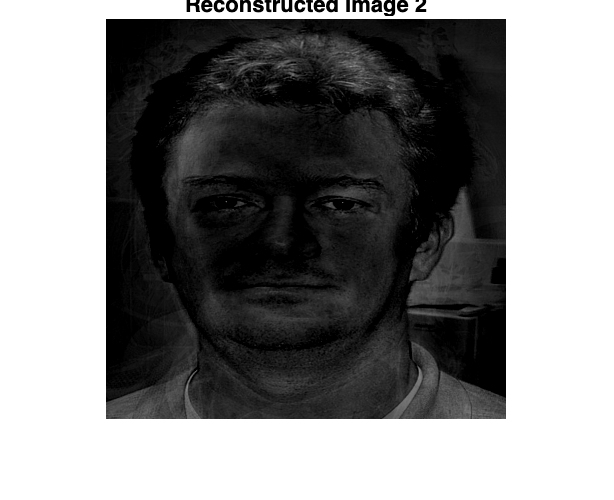

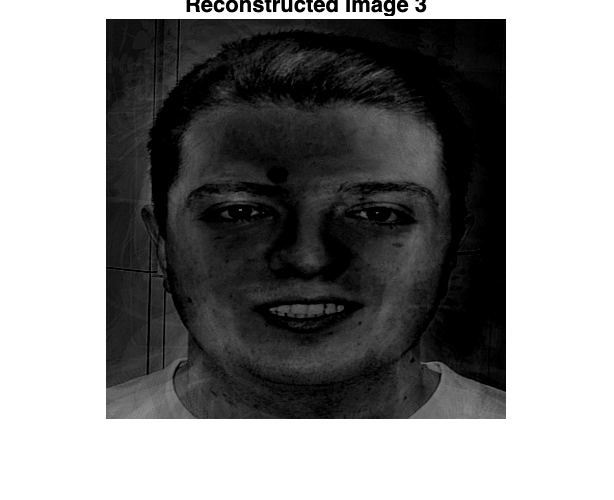

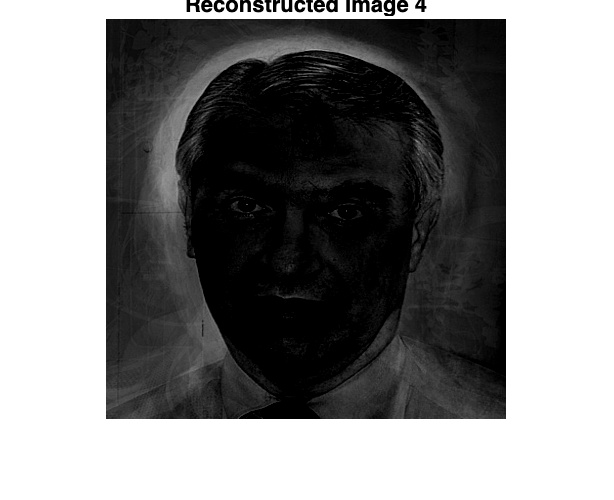

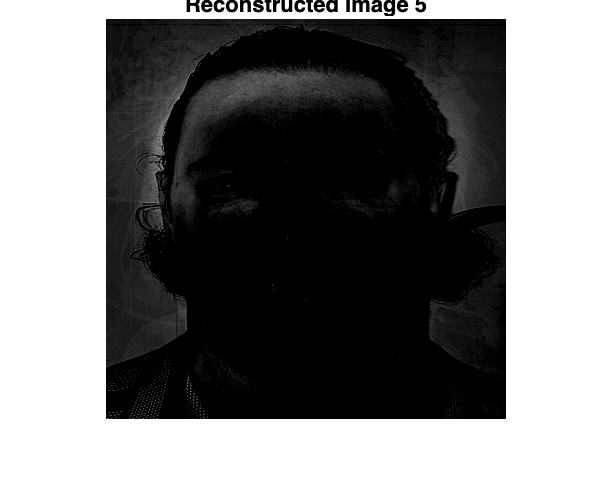

%img2 = imread("normalized_db0_2.jpg");
%imshow(img2)
% folder_path = "../Facial-recognition/db/DB2/";
folder_path = '../db/DB1/';
commonsize = [400, 400];

% Anropa funktionen och ta emot returvärdet
[DataMatrix, ~] = loadAndProcessImages(folder_path, commonsize);

% Beräkna medelvärdet för bildvektorerna
mean_vector = mean(DataMatrix);

% Subtrahera medelvärdet för att centrera data
centered_data = DataMatrix - mean_vector;

% Beräkna egenvärden, scores och eigenvalues med PCA
[eigenVectors, scores, eigenValues] = pca(centered_data);

% Transponera centered_data för att göra dimensionerna kompatibla för multiplikation
centered_data_transposed = centered_data';

% Beräkna vikter för varje ansikte i träningsuppsättningen
weights = eigenVectors' * centered_data_transposed;

% Återkonstruera ansikten från vikterna och de bästa egenvärdena (om så önskas)
reconstructed_data = eigenVectors * weights;

% Förutsatt att varje kolumn i DataMatrix representerar en bild
num_images_to_display = 5; % Antal bilder att visa

for i = 1:num_images_to_display
    % Återskapa varje bild från vikterna och de bästa egenvärdena
    reconstructed_image = reshape(reconstructed_data(:, i), commonsize);

    % Visa återskapad bild
    figure;
    imshow(uint8(reconstructed_image)); % Förutsatt att pixelvärdena är i 0-255-intervall
    title(['Reconstructed Image ', num2str(i)]);
end


save('eigen_data.mat', "eigenVectors",'eigenValues','scores')



















